load('testTrackSpatial.mat','track');
nFrame=120;
pixSizenm=65;
imSizePix=60;
sigmaPSFnm=300/2.35;
ringCentroid= [(imSizePix+1)/2+(rand(1)-0.5),(imSizePix+1)/2+(rand(1)-0.5)];
sigmaPSFpix= sigmaPSFnm/pixSizenm;
ii=1;
posX=ringCentroid(1)+track.x(ii)/pixSizenm;
posY=ringCentroid(2)+track.y(ii)/pixSizenm;
im= generateGaussPSFIm([posX,posY],sigmaPSFpix,imSizePix);

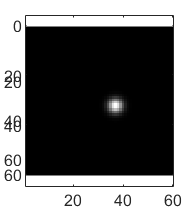

imagesc(im);
axis equal;
colormap gray;

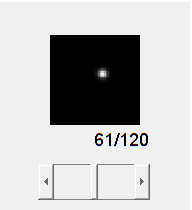

[ringStack, track2]=genTrackRingImage(track,nFrame, pixSizenm ,sigmaPSFnm, imSizePix);
sliceViewer(ringStack);